# MIC phase1:  Centre of MASS calcs - **3 bladed propeller **case

The purpose of this report is to calculate the position of a SYSTEM's center of mass (CM

**ATTENTION:  **

We need to calculate this so that we can then compute the systems inertia matrix relative to this CM co-ordinate.

Consider the quadrotor system shown below:

       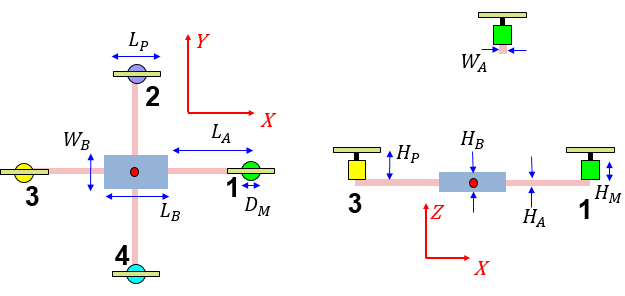  

## Let's define some of the geometry of the system

The body HUB:

L_B = 10/100;  % (m)
W_B = 10/100;  % (m)
H_B = 4/100;   % (m)

The ARMs:

L_A = 15/100;  % (m)
W_A = 1/100;   % (m) 
H_A = 1/100;   % (m)

The MOTORs:

D_M = 3/100;   % (m)
H_M = 4/100;   % (m)

The PROPELLERS:

The following properties are from the 3-blade Master Airscrew propeller listed [**HERE**](http://www.masterairscrew.com/collections/3-blade/products/3-blade-6x4-propeller)

prop_diam   = 0.152;       % (m)
L_P         = prop_diam;   % (m)
D_P         = 3.5/1000;    % (m) - estimated average thickness of blade
H_P         = 6/100;       % (m)
mass_P      = 6.8/1000;    % (kg)
mass_Pblade = mass_P/3;    % (kg) - mass of 1 blade of the propeller
blade_len   = prop_diam/2; % (m) 
blade_wid   = 1/100;       % (m) - estimated width of blade


## Specify the positions of each component's CM:

To start this CM calculation process, we'll define the local CM's of each of the components in the system  - and we'll decribe these local CMs relative to the "red dot".

Define data relative to the RED DOT

%      ID         mass(kg)    X_CG            Y_CG               Z_CG
C = { 'Motor_1',  50/1000,    (L_B/2 + L_A),   0,                 (H_A/2 + H_M/2);
      'Motor_2',  50/1000,     0,             (W_B/2 + L_A),      (H_A/2 + H_M/2);
      'Motor_3',  50/1000, -1*(L_B/2 + L_A),   0,                 (H_A/2 + H_M/2);
      'Motor_4',  50/1000,     0,             -1*(W_B/2 + L_A),   (H_A/2 + H_M/2);
      'HUB',     600/1000,     0,              0,                 0;
      'Prop_1',  6.8/1000,    (L_B/2 + L_A),   0,                 (H_A/2 + H_P);      
      'Prop_2',  6.8/1000,     0,             (W_B/2 + L_A),      (H_A/2 + H_P);
      'Prop_3',  6.8/1000, -1*(L_B/2 + L_A),   0,                 (H_A/2 + H_P);
      'Prop_4',  6.8/1000,     0,             -1*(W_B/2 + L_A),   (H_A/2 + H_P);
      'Arm_1',    25/1000,    (L_B/2 + L_A/2), 0,                 0;
      'Arm_2',    25/1000,     0,             (W_B/2 + L_A/2),    0;      
      'Arm_3',    25/1000, -1*(L_B/2 + L_A/2), 0,                 0;
      'Arm_4',    25/1000,     0,             -1*(W_B/2 + L_A/2), 0;  
      };

% create a TABLE  
TB_local_m_and_CG = cell2table(C(:,2:end), ...
                                'VariableNames', {'mass_kg', 'X_CG_m', 'Y_CG_m', 'Z_CG_m'}, ...
                                'RowNames', C(:,1) )

TB_local_m_and_CG = 13×4 table
               mass_kg    X_CG_m    Y_CG_m    Z_CG_m
               _______    ______    ______    ______

    Motor_1      0.05        0.2         0    0.025 
    Motor_2      0.05          0       0.2    0.025 
    Motor_3      0.05       -0.2         0    0.025 
    Motor_4      0.05          0      -0.2    0.025 
    HUB           0.6          0         0        0 
    Prop_1     0.0068        0.2         0    0.065 
    Prop_2     0.0068          0       0.2    0.065 
    Prop_3     0.0068       -0.2         0    0.065 
    Prop_4     0.0068          0      -0.2    0.065 
    Arm_1       0.025      0.125         0        0 
    Arm_2  

## Calculate the Center of MASS of the system relative to the RED DOT:

Total_mass = sum(TB_local_m_and_CG.mass_kg)   

Total_mass =    0.927200000000000


system_X_CG_m =  sum(TB_local_m_and_CG.mass_kg .* TB_local_m_and_CG.X_CG_m)/Total_mass;   
system_Y_CG_m =  sum(TB_local_m_and_CG.mass_kg .* TB_local_m_and_CG.Y_CG_m)/Total_mass;
system_Z_CG_m =  sum(TB_local_m_and_CG.mass_kg .* TB_local_m_and_CG.Z_CG_m)/Total_mass;

% so echo the system CM relative to the red dot
[system_X_CG_m; 
 system_Y_CG_m; 
 system_Z_CG_m]

ans =                    0
                   0
   0.007299396031061


## Define the component co-ords relative to the system CM

Next, let's specify the local component CM's relative to the system's CM

TB_comp_sys_CG        = TB_local_m_and_CG;
TB_comp_sys_CG.X_CG_m = TB_comp_sys_CG.X_CG_m - system_X_CG_m;
TB_comp_sys_CG.Y_CG_m = TB_comp_sys_CG.Y_CG_m - system_Y_CG_m;
TB_comp_sys_CG.Z_CG_m = TB_comp_sys_CG.Z_CG_m - system_Z_CG_m;

TB_comp_sys_CG

TB_comp_sys_CG = 13×4 table
               mass_kg    X_CG_m    Y_CG_m           Z_CG_m       
               _______    ______    ______    ____________________

    Motor_1      0.05        0.2         0      0.0177006039689387
    Motor_2      0.05          0       0.2      0.0177006039689387
    Motor_3      0.05       -0.2         0      0.0177006039689387
    Motor_4      0.05          0      -0.2      0.0177006039689387
    HUB           0.6          0         0    -0.00729939603106126
    Prop_1     0.0068        0.2         0      0.0577006039689387
    Prop_2     0.0068          0       0.2      0.0577006039689387
    Prop_3     0.0068       -0.2         0      0.0577006039689387
    Prop_4  

# MIC phase2:  INERTIA calcs

In phase2 we're going to calculate the inertia matrix for the system.

To do this we'll calculate the inertia matrix of each component relative to the system's Centre of mass frame.  For each component we'll apply the classic Parallel Axis theorem, ie:


$$I_o = I_{CM} + m * A$$
 

where:

$A =   \pmatrix{ 
 (y_c^2 + z_c^2),         -{x_c}*{y_c},          -x_c*z_c \cr
                             -x_c*y_c,  (x_c^2 + z_c^2),         -y_c*z_c \cr
                             -x_c*z_c,         -y_c*z_c,  (x_c^2 + y_c^2) \cr

} 
$  and $ r_c = \pmatrix{  x_c \cr y_c \cr z_c

} $

$r_c$ defines the position of the component's center of mass releative to the SYSTEM's centre of mass, and $m$ is the component's mass

## The INERTIA building blocks:

We're going to approximate the component inertias using brick's and cylinders.

 

**The MOTORS:**

  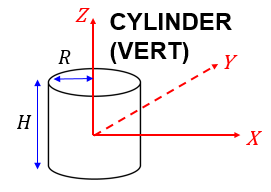

H_mot    = H_M;
R_mot    = D_M/2;
mass     = TB_comp_sys_CG{'Motor_1', 'mass_kg'};
%
% calculate the local INERTIA matrix
shape     = inertia_cylinder_VERT_CLS(H_mot, R_mot, mass);
I_LOC     = shape.get_I();
% for each motor, apply the Parallel Axis Theorem
rc_part_1 = TB_comp_sys_CG{'Motor_1', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_2 = TB_comp_sys_CG{'Motor_2', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_3 = TB_comp_sys_CG{'Motor_3', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_4 = TB_comp_sys_CG{'Motor_4', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };

OBJ_1 = inertia_parallel_local_to_desired_CLS(rc_part_1, I_LOC, mass);
OBJ_2 = inertia_parallel_local_to_desired_CLS(rc_part_2, I_LOC, mass);
OBJ_3 = inertia_parallel_local_to_desired_CLS(rc_part_3, I_LOC, mass);
OBJ_4 = inertia_parallel_local_to_desired_CLS(rc_part_4, I_LOC, mass);

sub_total_I_motors = OBJ_1.calc_I_GLOB() + ...
                     OBJ_2.calc_I_GLOB() + ...
                     OBJ_3.calc_I_GLOB() + ...
                     OBJ_4.calc_I_GLOB()

sub_total_I_motors =    0.004100578942840                   0                   0
                   0   0.004100578942840                   0
                   0                   0   0.008022500000000


**The Propellers :**

We are using a 3 bladed propeller similar to the Master Airscrew propeller listed [**HERE**](http://www.masterairscrew.com/collections/3-blade/products/3-blade-6x4-propeller).

       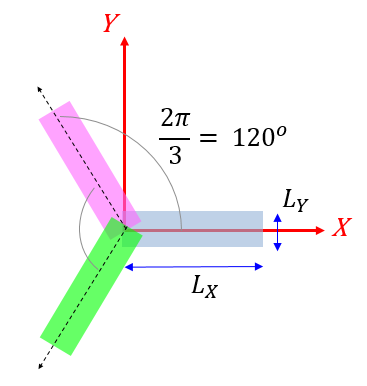


mass  = mass_Pblade;
%
% calculate the local INERTIA matrix

shape   = inertia_3bladed_trp_propeller_CLS(blade_len, blade_wid, mass);
I_LOC   = shape.get_I();

% for each propeller, apply the Parallel Axis Theorem
rc_part_1 = TB_comp_sys_CG{'Prop_1', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_2 = TB_comp_sys_CG{'Prop_2', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_3 = TB_comp_sys_CG{'Prop_3', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_4 = TB_comp_sys_CG{'Prop_4', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };

OBJ_1 = inertia_parallel_local_to_desired_CLS(rc_part_1, I_LOC, mass);
OBJ_2 = inertia_parallel_local_to_desired_CLS(rc_part_2, I_LOC, mass);
OBJ_3 = inertia_parallel_local_to_desired_CLS(rc_part_3, I_LOC, mass);
OBJ_4 = inertia_parallel_local_to_desired_CLS(rc_part_4, I_LOC, mass);

sub_total_I_props =  OBJ_1.calc_I_GLOB() + ...
                     OBJ_2.calc_I_GLOB() + ...
                     OBJ_3.calc_I_GLOB() + ...
                     OBJ_4.calc_I_GLOB()

sub_total_I_props =    1.0e-03 *

   0.237817394598648                   0                   0
                   0   0.237817394598648                   0
                   0                   0   0.415262400000000


**The Arms :**

   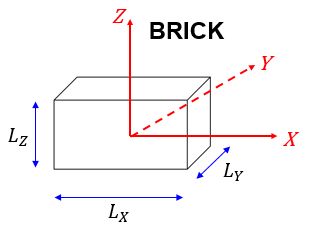

%  ARMS 1            ARMS 2  
%  and 3             and 4
Lx_13 = L_A;      Lx_24 = W_A;
Ly_13 = W_A;      Ly_24 = L_A;
Lz_13 = H_A;      Lz_24 = H_A;

mass   = TB_comp_sys_CG{'Arm_1', 'mass_kg'};
%
% calculate the local INERTIA matrix
shape_13 = inertia_brick_CLS(Lx_13, Ly_13, Lz_13, mass);
shape_24 = inertia_brick_CLS(Lx_24, Ly_24, Lz_24, mass);

I_LOC_13 = shape_13.get_I();
I_LOC_24 = shape_24.get_I();
% for each arm, apply the Parallel Axis Theorem
rc_part_1 = TB_comp_sys_CG{'Arm_1', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_2 = TB_comp_sys_CG{'Arm_2', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_3 = TB_comp_sys_CG{'Arm_3', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };
rc_part_4 = TB_comp_sys_CG{'Arm_4', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };

OBJ_1 = inertia_parallel_local_to_desired_CLS(rc_part_1, I_LOC_13,    mass);
OBJ_2 = inertia_parallel_local_to_desired_CLS(rc_part_2,    I_LOC_24, mass);
OBJ_3 = inertia_parallel_local_to_desired_CLS(rc_part_3, I_LOC_13,    mass);
OBJ_4 = inertia_parallel_local_to_desired_CLS(rc_part_4,    I_LOC_24, mass);

sub_total_I_arms =   OBJ_1.calc_I_GLOB() + ...
                     OBJ_2.calc_I_GLOB() + ...
                     OBJ_3.calc_I_GLOB() + ...
                     OBJ_4.calc_I_GLOB()

sub_total_I_arms =    0.000881578118242                   0                   0
                   0   0.000881578118242                   0
                   0                   0   0.001750833333333


**The HUB :**

   

Lx = L_B;      
Ly = W_B;      
Lz = H_B;      

mass   = TB_comp_sys_CG{'HUB', 'mass_kg'};
%
% calculate the local INERTIA matrix
shape = inertia_brick_CLS(Lx, Ly, Lz, mass);
I_LOC = shape.get_I();
% for each HUB, apply the Parallel Axis Theorem
rc_part_1 = TB_comp_sys_CG{'HUB', {'X_CG_m','Y_CG_m', 'Z_CG_m'} };

OBJ_1 = inertia_parallel_local_to_desired_CLS(rc_part_1, I_LOC, mass);

sub_total_I_hub =   OBJ_1.calc_I_GLOB() 

sub_total_I_hub =    1.0e-03 *

   0.611968709450964                   0                   0
                   0   0.611968709450964                   0
                   0                   0   1.000000000000000


**Now combine ALL of these inertias:**

Total_inertia =  sub_total_I_motors + ...
                 sub_total_I_props  + ...
                 sub_total_I_arms   + ...
                 sub_total_I_hub   

Total_inertia =    0.005831943165131                   0                   0
                   0   0.005831943165131                   0
                   0                   0   0.011188595733333


Also, what is the airframe inertia when we exclude the rotating components(ie: propellers):

Total_without_props =  sub_total_I_motors + ...
                       sub_total_I_arms   + ...
                       sub_total_I_hub                

# SUMMARY 

The total system MASS and INERTIA is:

format long
Total_mass

Total_mass =    0.927200000000000


Total_inertia

Total_inertia =    0.005831943165131                   0                   0
                   0   0.005831943165131                   0
                   0                   0   0.011188595733333



% save to a MAT file
my_TIMESTAMP = datestr(now)

my_TIMESTAMP = '02-Sep-2017 14:09:26'

save bh_SYSTEM_m_and_I  Total_mass  Total_inertia my_TIMESTAMP